# MA5801: Assignment 4 - Principal Component Analysis

Nicholas Moellers 

Implement principal component analysis (PCA) using a singular value decomposition on a real dataset.

## Introduction

As a global community, there has been significant in roads made to build a global economy, raising nations out of poverty and providing a better standard of living. However, growing populations mean access to food and clean water can be sparse. In developing nations, whilst many opportunities exist for investment, the level of education and skill for workers may be quite low. This also correlates to lower life expectancy due to lack of health resources. Often, as can be seen in India, where there is low life expectancy, there is a high population of people under 15 years of age. This report seeks to explore the issues from a Tropics perspective and analyse the principal components and determine the strength and relationship of variables.

## Data

The data comes from State of the Tropics - Poverty – Undernourishment, which is calculated from FAO - VAO1 Number of people undernourished **[1]**. The data consists of 14 variables and 109 records. Country is the only categorical variable and will be removed to perform the PCA. The remaining variables are numerical: Life Expectancy (years), Poverty under $1.25 per day, Population under 15, Adult literacy (% above 15), Mean years of schooling, Unemployment (%), Youth literacy (% age 15-24), Tuberculosis (cases), Under 5 mortality (under age 5 per 1000 births), Poverty under $2 per day, Undernourishment, Urban population (%), Area of agricultural land (??).

Rows with missing values were excluded, there was 53 NaN’s removed, resulting in a 56 x 13 matrix. Prior to the analysis, there was no scaling of the data except for the calculations of percentages such as Unemployment %.

format shortG

% Import raw data from excel file
Xshift = xlsread('SotTCombined2010.xlsx');

% Exclude rows with missing values
rows = any(isnan(Xshift),2);
Xshift(rows,:) = [];
Xshift;

## Analysis

When conducting the analysis, Matlab version R2019b **[2]** was used. To make the results more readable, the format was set to shortG. Next, the an excel document was read in as a numeric matrix, this removed the Country field. In order to perfom the PCA, there must not be any missing values within the data, as such, all rows containing missing data were removed. The matrix was then scaled to assist in comparison of the variables; resulting in a 53x13 matrix.

% Compute means and variance of each column
colmeans = mean(Xshift,1);
colvars = var(Xshift,1);

% Compute the X matrix from the raw data
X = (Xshift - repmat(colmeans, size(Xshift,1), 1)) ./ repmat(sqrt(colvars), size(Xshift,1), 1);

% Size of Resulting matrix
size(X)

ans =     56    13


Using the scaled matrix, the SVD was calculated using the svd() function **[3]**. From this, the weights were then calculated and a used to compute the ratio of each component to the sum of the weights.

The cumulative sum was then calculated and plotted to identify the sums of each component., the cumulative su plot will be useful in determining what features exlained the variance.

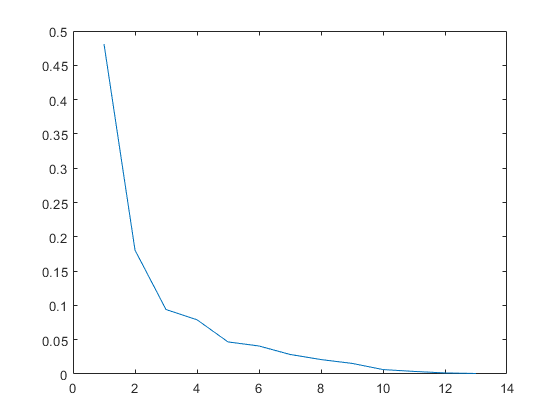


% Perform the SVD of the scaled matrix
[U,S,V] = svd(X);
% Grab the weights for PCA
weights = diag(S).^2;

% Compute the ratio of each component to the total sum of the weights
prop_weights = weights / sum(weights);

% Plot prop_weights
plot(prop_weights)

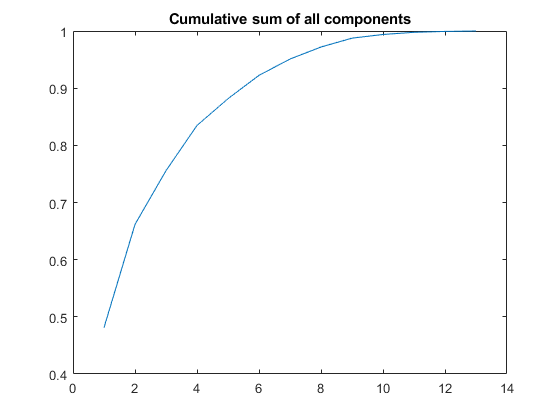

% Cumulative sum demonstrates how much of the space is represented by sums
% of 1st, 1st and 2nd, all components 
cumprop_weights = cumsum(prop_weights);

figure
plot(cumprop_weights)
title('Cumulative sum of all components')

% Compute the reduced matrix from only first two components
reduced = U * S(:,1:2) * V(:,1:2)';
% Compute the residuals
residuals = sum((X - reduced).^2,2);
% Compute the score matrix
T = U*S;


To identify outlier countries, the data was read into a table and rows containing missing data were removed. The resulting table was then joined with the residuals from the PCA's for further analysis which will be referenced in the discussion.

% Exclude rows with missing values
sotdata = readtable("SotTCombined2010.xlsx");

sotdatarm = rmmissing(sotdata);
R = array2table(residuals);

% Join tables
joinedData = horzcat(sotdatarm,R)

joinedData = 56×15 table
                  Country                   LifeExpectancy_years_    PovertyUnder_1_25PerDay    PopulationUnder15    AdultLiteracy__Above15_    MeanYearsOfSchooling    Unemployment___    YouthLiteracy__Age15_24_    Tuberculosis_cases_    Under5Mortality_underAge5Per1000Births_    PovertyUnder_2PerDay    Undernourishment    UrbanPopulation___    AreaOfAgriculturalLand____    residuals
    ____________________________________    _____________________    _______________________    _________________    _______________________    ____________________    _______________    ___________________

%stackedplot(joinedData)
countries= joinedData{:,1};
resV = joinedData{:,"residuals"};
%plot residuals against country for visual analysis

## Discussion

Given that all rows containing NaN values were removed, it was possible to apply SVD to the data. The cumulative sum of all componentts showed that 49% of the total variance was explained by the first component and ~75% by the first three.

From the PCA, it was identified, Life expectancy was the most important component. Life expectancy is very closely tied to the other principal components such as deaths under 5, poverty, tuberculosis and malnourishment. 

Furthermore, when combining the residual values with countries, Brazil, Namibia and Mauritania were identified as outliers. The table also revealed that Australia was excluded for having missing values; the countries remaining are all considered to be developing nations.

Further analysis of these outliers shows Brazil has the highest life expectancy of the three with 72, close to the overall highest life expectancy of 78 from the filtered data and compared to 81 for Australia which has the second highest life expectancy behind China (82).

Likewise, Brazil also had high rates of adult/youth literacy and low unemployment rates. However, the number of tuberculosis cases were higher that of similar countries. Brazil also showed a higher number for agricultural land area. Thus, these fields attributed to it being categorised as an outlier.

Mauritania and Namibia were similar in most aspects with the life expectancy differing by 0.613. However, Namibia had a much higher rate of  Adult and youth literacy, as well as a greater number of years schooling. This resulted in reduced under 5 mortality rates but did not improve other aspects. It is not clear on the reasons for this. Further data is required.

The SVD/PCA shows that lfie expectancy is closely tied to education, disease prevention and food availaility. This is highlighted in other studies such as "The impact of increasing education levels on rising life expectancy" **[4]**. The greatest rise in life expectancy came from disease prevention.

There was difficulty in plotting the country against residuals due to data types, so the table was sorted by residual to assist in the analysis; visual analysis is preferred as it offers better readability.

## Conclusion

From the PCA analysis using SVD, it was found that Brazil, Namibia and Mauritania were outliers. Additionally, the data showed that 49% of the total variance was explained by the first principal component.

Countries with a high poverty rate such as the Democratic Peoples Republic of Congo were also found to have a lower life expectancy, high rates of undernourishment, high rates of tuberculosis and low mean for years of schooling.

These results highlight the need for increased education to support developing nations and assist in disease prevention.

## References

[1] Referenced by initial dataset. Unable to access. [http://www.fao.org/hunger/en/Prevalence](http://www.fao.org/hunger/en/Prevalence)

[2] Matlab R2019b, Copyright 1984-2005 The MathWorks, Inc.

[3] svd(), Copyright 1984-2005 The MathWorks, Inc.

[4] Luy, M., Zannella, M., Wegner-Siegmundt, C. *et al.* The impact of increasing education levels on rising life expectancy: a decomposition analysis for Italy, Denmark, and the USA. *Genus* **75, **11 (2019) doi:10.1186/s41118-019-0055-0